Este script es para ir tanteando

clear

# Cosas básicas

Empezamos importando los datos. Están en formato h5, por lo que se puede acceder "lazily" (no necesita cargar el archivo completo en memoria). En particular, para este archivo tiene un "chunk" por cada electrodo, es decir que la forma más eficiente de acceder es por dim=2.

% Información del archivo .h5
path = "..\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

Por ejemplo, podemos cargar la señal del electrodo 1:

electrode = 1;
signal = h5read(filename, dataset, [1, electrode], [num_times, 1]);
signal = signal(~isnan(signal)); % elimina las entradas NaN (son sólo los últimos elementos)

El argumento 3 de h5read indica el primer elemento a leer del archivo y el argumento 4 indica cuántas filas y columnas se van a leer desde ese punto.

Grafiquemos esa señal. Como tiene del orden de 10^6 puntos, graficamos los primeros 5*

10^4 puntos para que se aprecie mejor:

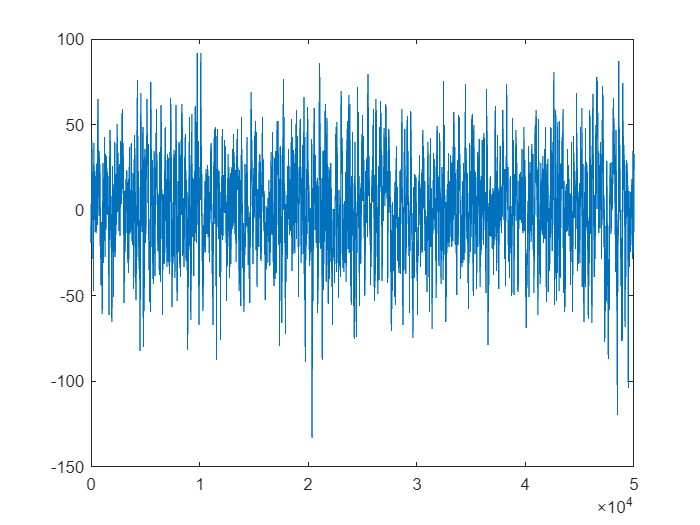

figure(1);
plot(signal(1:5e4));
hold off

# Transformada de Fourier y espectro de potencia

Ahora veamos la transformada de Fourier y el espectro de potencia de la señal

tf = fftshift(fft(signal));
ps_bilateral = pspectrum(signal, "TwoSided", true);

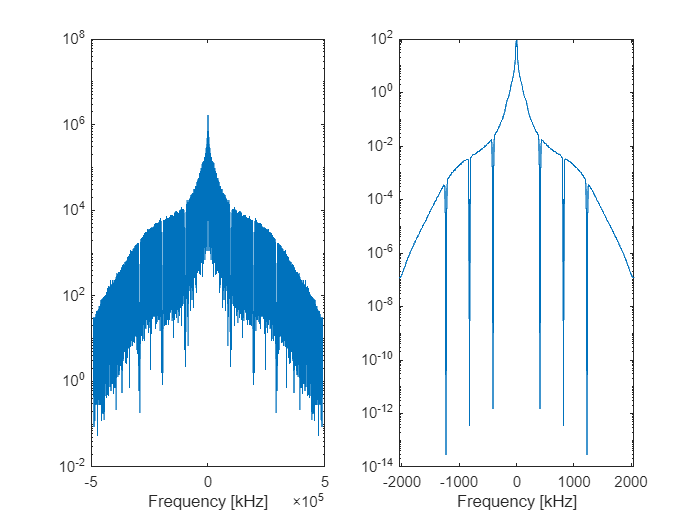

Fs = 30; % kHz

figure(2);

l = length(tf);
f = (-l/2:l/2-1); % /l*Fs; para expresar en kHz
subplot(1,2,1);
semilogy(f, abs(tf));
xlabel("Frequency [kHz]");

l = length(ps_bilateral);
f = (-l/2:l/2-1); %/l*Fs; para expresar en kHz
subplot(1,2,2);
semilogy(f, ps_bilateral);
xlabel("Frequency [kHz]");
hold off

O grafiquemos el espectro de potencia en escala loglog.

ps = pspectrum(signal);

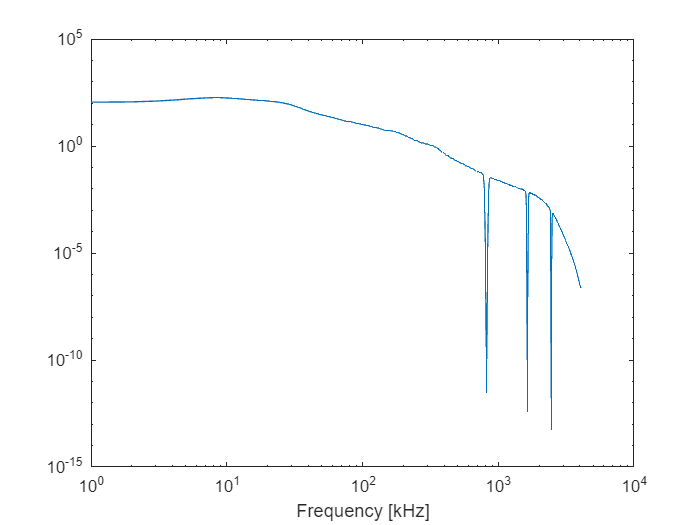

figure(3);
l = length(ps);
f = (1:l); % /l*Fs; para expresar en kHz
subplot(1,1,1)
loglog(f, ps);
xlabel("Frequency [kHz]");
hold off

# Detrended Fluctuation Analysis

Ahora realicemos DFA (detrended fluctuation analysis).

n_max = log10(length(signal)); % máximo valor para la "box length"
box_lengths = floor(logspace(1, n_max, 100));
[A,F] = DFA_fun(signal,box_lengths);

F_powerlaw = @(x) (log10(F(1))+(x-log10(box_lengths(1)))); % curva para ruido 1/f en loglog
F_brown = @(x) (log10(F(1))+1.5*(x-log10(box_lengths(1)))); % curva para ruido Browneano en loglog

x0 = log10(box_lengths(1));
x1 = log10(box_lengths(end));
x = [x0, x1];

figure(4);
subplot(1,1,1);
scatter(log10(box_lengths),log10(F));
plot( x, arrayfun(F_powerlaw, x), '--' );
plot( x, arrayfun(F_brown, x), '--' );
legend('data', '1/f', 'Brownian');

int1 = box_lengths < 10^2;
int2 = (box_lengths>10^4) & (box_lengths<10^5.5);

Ajuste lineal de F(n) en loglog en el intervalo int1:

polyfit(log(box_lengths(int1)), log(F(int1)), 1)

Ajuste en el intervalo int2:

polyfit(log(box_lengths(int2)), log(F(int2)), 1)

# DFA por cuadrantes

Hacemos DFA para cada cuadrante dentro de un dado array y comparamos.

signal = h5read(filename, dataset, [1 1], [num_times 64]);
signal = signal(1:9e5,:);

left = @(id) (mod(id-1, 8) <= 3);
top = @(id) (floor((id-1) / 8) <= 3);

cuadrante1 = signal(:, left(1:64) & top(1:64));
cuadrante2 = signal(:, ~left(1:64) & top(1:64));
cuadrante3 = signal(:, left(1:64) & ~top(1:64));
cuadrante4 = signal(:, ~left(1:64) & ~top(1:64));

cuadrantes = cat(3, cuadrante1, cuadrante2, cuadrante3, cuadrante4);

n_max = log10(length(cuadrante1)); % máximo valor para la "box length"
box_lengths = floor(logspace(1, n_max, 20));
F = zeros(4, length(box_lengths));

for i=1:4
    disp(i);
    q=mean(cuadrantes(:,:,i), 2);
    [A,f] = DFA_fun(q,box_lengths,1);
    F(i, :) = f;
end

     1

     2

     3

     4



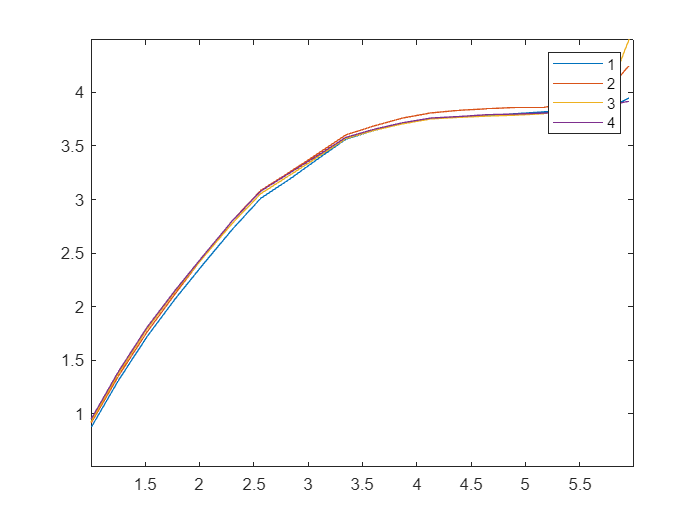

figure(100);
subplot(1,1,1);
for i=1:4
    plot(log10(box_lengths),log10(F(i, :)));
    hold on
end
legend('1', '2', '3', '4');
hold off

savefig("dfa_cuadrantes_array1.fig");